# Foveal pit shape

This tutorial explains how to compute geometrical features that describe the foveal pit.

The steps followed:

- Load an OCT image into MATLAB

- Flatten the retina (computing total retinal thickness map)

- Rearange sample points into a radial pattern (if needed)

- Compute foveal shape parameters

If you need help please reach out at **dromero@mondragon.edu**

close all; clc; clearvars;
addpath(genpath('../src'));

## Load a file

This step loads the information inside the file and computes the X, Y coordinates of each A-scan.

For foveal analysis we only need the header and segmentation data but we also read B-scans to create some visualizations.

file = '../src/data/raster.vol';
[header, seg, bscan] = read_vol(file, 'get_coordinates');

X = header.X_oct;
Y = header.Y_oct;

## **Flatten the retina**

Before computing geometrical parameters a common step is to flatten the retina by computing the total retinal thickness (TRT).

This step sets the BM as a flat reference and generates a more prominent rim.

To do so, we need to have segmented the inner limiting membrane (ILM) and the Bruch's membrane (BM) shown below:

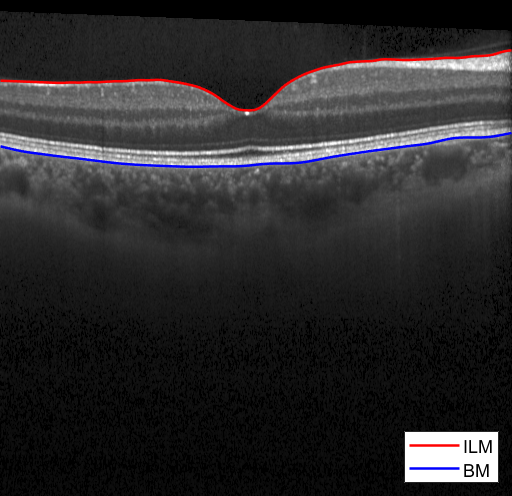

f = figure('Position', [0 0 600 500]);
imshow(bscan(:,:,13)); hold on;
plot(seg.ILM(13,:), 'r', 'LineWidth', 1.5);
plot(seg.BM(13,:),  'b', 'LineWidth', 1.5);
legend({'ILM','BM'}, 'Location', "southeast");

set(gca, 'FontSize', 12);

From segmented data we compute the TRT

Thickness = compute_thickness(seg, 'TRT', header.scale_z);
TRT = Thickness.TRT;

We can visualize the obtained TRT profile (for the middle B-scan)

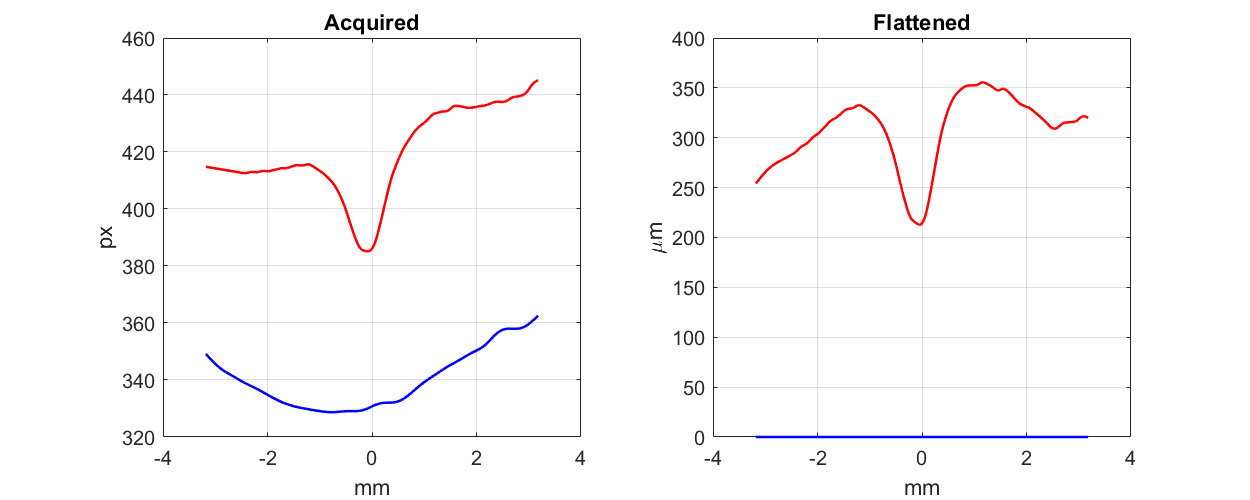

f = figure('Position', [0 0 1000 400]);

subplot(121); hold on;
plot(X(13,:), header.n_axial - seg.ILM(13,:), 'r', 'LineWidth', 1.5);
plot(X(13,:), header.n_axial - seg.BM(13,:), 'b', 'LineWidth', 1.5);
xlabel('mm'); ylabel('px'); title('Acquired');
grid on; box on; set(gca, 'FontSize', 12);

subplot(122); hold on;
plot(X(13,:), TRT(13,:), 'r', 'LineWidth', 1.5);
plot(X(13,:), zeros(1, header.n_ascan), 'b', 'LineWidth', 1.5)
xlabel('mm'); ylabel('\mum'); title('Flattened');
grid on; box on; set(gca, 'FontSize', 12);

Note that the left plot is in pixel units while the second is in micrometers.

## Foveal parameter extraction

In the simplest case, we may just want to compute parameters for the middle B-scan.

We need to find the fovea as the point of minimum TRT and convert our middle B-scan TRT profiles into left and right.

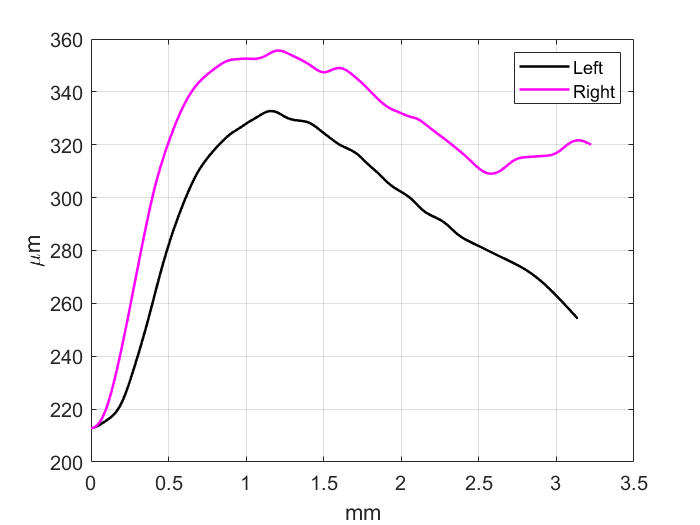

idx_bscan = 13;
[~, idx_fovea] = min(TRT(idx_bscan, :));
x = X(idx_bscan, :);
x = x - x(idx_fovea);

rho_right = x(idx_fovea:end);
rho_left  = abs(x(idx_fovea:-1:1));
trt_right = TRT(idx_bscan, idx_fovea:end);
trt_left  = TRT(idx_bscan, idx_fovea:-1:1);

f = figure; hold on;
plot(rho_left, trt_left, 'k','LineWidth',1.5);
plot(rho_right, trt_right,'m','LineWidth',1.5);
xlabel('mm'); ylabel('\mum');
grid on; box on; legend({'Left','Right'});
set(gca,'FontSize',12);

In the example we see the right part is thicker as it corresponds with the nasal sector (the example is a right eye).

To extract foveal parameters we need to build a matrix with a row two rows for left and right.

We pad the left side with NaNs to have the same lenght as the right

n_extra = length(rho_right) - length(rho_left);

rho_left = [rho_left nan(1, n_extra)];
trt_left = [trt_left nan(1, n_extra)];

We build the matrix and compute the parameters

rho = [rho_right; rho_left];
trt = [trt_right; trt_left];

parameters = {'rim_height', 'rim_radius', 'mean_slope'};
Z = get_morph_params(rho, trt, parameters, false)

Z = struct with fields:
    rim_height: [355.6508 332.7438]
    rim_radius: [1.2075 1.1577]
    mean_slope: [6.6657 5.8840]


The resulting parameters are stored in a struct with a value for each direction.

We can even visualize the rim parameter

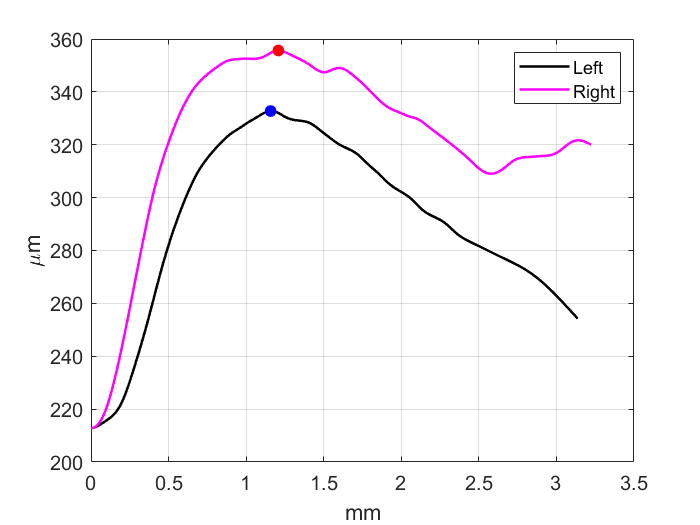

f = figure; hold on;
plot(rho_left, trt_left, 'k','LineWidth',1.5);
plot(rho_right, trt_right,'m','LineWidth',1.5);
scatter(Z.rim_radius(1), Z.rim_height(1), 50, 'r', 'filled');
scatter(Z.rim_radius(2), Z.rim_height(2), 50, 'b', 'filled');
xlabel('mm'); ylabel('\mum');
grid on; box on;
legend({'Left','Right'});
set(gca,'FontSize',12);

## Radial analysis

Often, we are interested in analyzing the foveal shape for different angular directions and not just the middle B-scan.

To do this we have two options:

- Acquire radial B-scans

- Interpolate raster B-scans into a radial pattern

Here we explain the second approach.

First it is crucial that we set the coordinate origin at the center of the foveal pit.

x_fovea, y_fovea = find_fovea(X, Y, TRT)
X = x - x_fovea;
Y = y - y_fovea;

In our case we have 25 raster B-scans so we apply interpolation to transform our data points into a radial (star) pattern:

[X_rad, Y_rad, TRT_rad] = resample_map(X, Y, TRT, 'star', 'max_d', 3, 'n_angle', 20, 'n_point', 100);

We can compare the sampling patterns

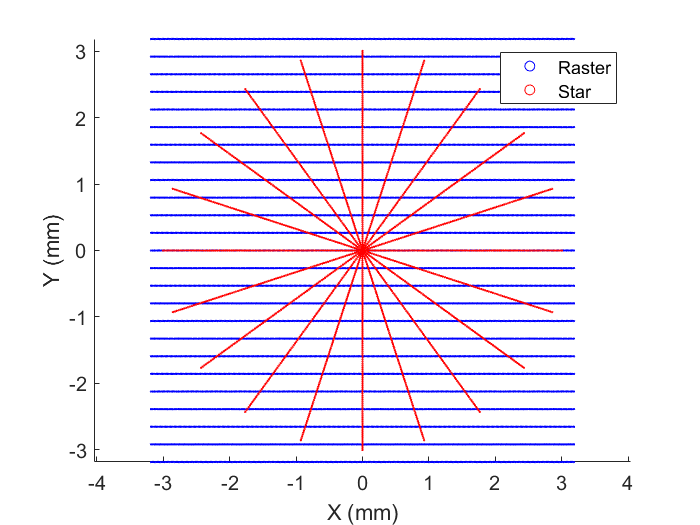

f = figure;
scatter(X(:), Y(:), 1, 'b'); hold on;
scatter(X_rad(:), Y_rad(:), 1, 'r');
axis equal;

xlabel('X (mm)'); ylabel('Y (mm)'); set(gca,'FontSize', 12);
legend({'Raster','Star'});

Now we transform X, Y into $\theta$,r polar coordinates to get the distance from the fovea on each point.

[theta, rho] = cart2pol(X_rad, Y_rad);

We can visualize the TRT profiles for every angular direction

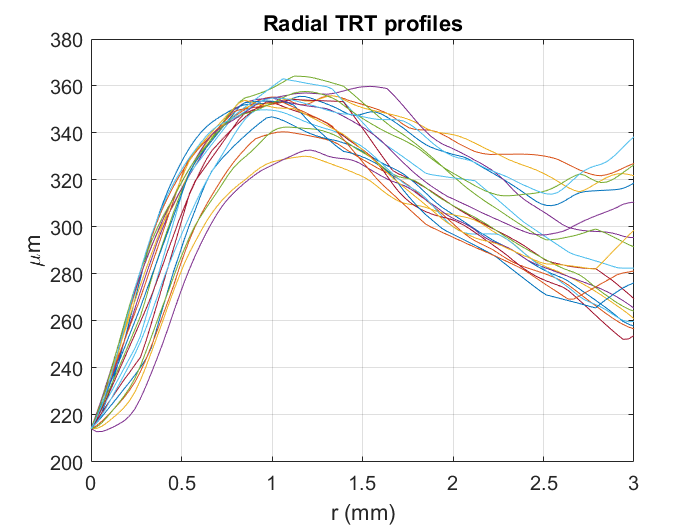

f = figure;
plot(rho(1,:), TRT'); hold on;
xlabel('r (mm)'); ylabel('\mum'); title('Radial TRT profiles'); 
grid on; set(gca,'FontSize', 12);

To compute parameters for every angular direction we use the same function

Z_rad = get_morph_params(rho_rad, TRT_rad, 'all', false)

Z_rad = struct with fields:
                     cft: [214.1554 214.1554 214.1554 214.1554 214.1554 214.1554 214.1554 214.1554 214.1554 214.1554 214.1554 214.1554 214.1554 214.1554 214.1554 214.1554 214.1554 214.1554 214.1554 214.1554]
               max_slope: [16.7192 16.6323 15.5662 13.5352 15.1395 14.8241 14.8009 15.1546 13.4349 12.2763 12.6848 12.0566 12.3866 12.2976 12.2091 12.8545 12.9660 14.5104 15.2979 16.0268]
        max_slope_radius: [0.2424 0.2121 0.2121 0.2727 0.3333 0.3333 0.5152 0.3636 0.4848 0.4242 0.4545 0.3636 0.3939 0.4242 0.3333 0.5152 0.1818 0.1818 0.1818 0.2121]
        max_slope_height: [269.0010 264.4034 263.4303 272.5640 277.7494 269.6598 306.5386 256.8301 281.8687 266.0720 263.4005 259.6665 276.4473 289.8735 278.7416 324.7628 254.6848 257.7076 258.3812 265.2431]
     max_slope_disk_area: 0.3598
    max_slope_disk_perim: 2.7451
              mean_slope: [6.9204 5.9999 6.0117 5.3405 7.5840 7.9449 7.0717 7.5180 6.7657 5.5762 5.5555 6.6877 7.9480 7.8879 8.1479 7.

If we only want radial averages just pass true to the last argument

Z_rad_avg = get_morph_params(rho_rad, TRT_rad, 'all', true)

Z_rad_avg = struct with fields:
                     cft: 214.1554
               max_slope: 14.0687
        max_slope_radius: 0.3318
        max_slope_height: 272.8513
     max_slope_disk_area: 0.3598
    max_slope_disk_perim: 2.7451
              mean_slope: 7.1234
              min_height: 214.0940
                pit_area: 0.1319
               pit_depth: 137.4729
              pit_volume: 0.1264
              rim_height: 351.6283
              rim_radius: 1.1121
           rim_disk_area: 3.8572
          rim_disk_perim: 7.5561
